# ANALYSIS   PERFORMED  

## section: READ DATA from files

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% NOTE: To run the analysis you need to download the NFB repository. 
% when repeating the analysis we simply use: 
clear; clc;
load('NPEP.mat','SUB', 'SUB_diagnosis') % and ignore the rest of this section
% Alternatively, uncoment the commented subsection starting three lines below.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%{
% READ DATA from Rockland open-source repository folder structure tsv files
fileID=fopen('../Data/output/participants.tsv','r');
SUB_info=textscan(fileID,'%s %s %s %s');
fclose(fileID);

% read data from each subject
nfb_sub=1;
for s=2:942
    if ([(['../Data/output/sub-' SUB_info{1}{s} '/ses-NFB3/func/sub-' SUB_info{1}{s} '_ses-NFB3_task-DMNTRACKINGTEST_events.tsv'])  
        fileID=fopen(['../Data/output/sub-' SUB_info{1}{s} '/ses-NFB3/func/sub-' SUB_info{1}{s} '_ses-NFB3_task-DMNTRACKINGTEST_events.tsv'],'r');    
        SUB_NFB=textscan(fileID,'%s %s %s %s %s %s %s %s','delimiter',{'\t'});

        SUB(nfb_sub).id           = SUB_info{1}{s};(nfb_sub).id           = SUB_info{1}{s};
        SUB(nfb_sub).age          = SUB_info{2}{s};(nfb_sub).age          = SUB_info{2}{s};
        SUB(nfb_sub).sex          = SUB_info{3}{s};(nfb_sub).sex          = SUB_info{3}{s};
        SUB(nfb_sub).handedness   = SUB_info{4}{s}; (nfb_sub).handedness   = SUB_info{4}{s}; 
        SUB(nfb_sub).data         = SUB_NFB{8};  (nfb_sub).data         = SUB_NFB{8};  % SUB(nfb_sub).data(strcmp('',SUB(nfb_sub).data)) = [];                   % ~ 8th column
        SUB(nfb_sub).instruction  = SUB_NFB{5};  (nfb_sub).instruction  = SUB_NFB{5};  % SUB(nfb_sub).instruction(strcmp('',SUB(nfb_sub).instruction)) = [];     % ~ 5th column
        SUB(nfb_sub).left_text    = SUB_NFB{3};  (nfb_sub).left_text    = SUB_NFB{3};  % SUB(nfb_sub).left_text(strcmp('',SUB(nfb_sub).left_text)) = [];         % ~ 3rd column
        SUB(nfb_sub).right_text   = SUB_NFB{4};  (nfb_sub).right_text   = SUB_NFB{4};  % SUB(nfb_sub).right_text(strcmp('',SUB(nfb_sub).right_text)) = [];       % ~ 4th column
        
        nfb_sub = nfb_sub + 1;
   end
end
clear SUB_info;

% READ DATA from Rockland diagnostic information file (DTA required)
fileID=fopen('../DUA/assessment_data/DiagnosticInfo.csv','r');         % note name of file changed for purposes of data protection
SUB_diagnosis=textscan(fileID,'%s %s %s %s %s %s %s %s %s %s %s %s','Delimiter',',');
fclose(fileID);
save NPEP.mat SUB SUB_diagnosis
%}

## section:  Determine Clinical Status from Diagnostic Info data



try  for line=1:1061; if strcmp(SUB_diagnosis{1}(line), '"#CODE:  #DESC:  #SPEC:"'); for col=1:12; SUB_diagnosis{col}(line)=[]; end; end; end; catch; end 
try  for line=1:1061; if strcmp(SUB_diagnosis{1}(line), '"#CODE:300.4  #DESC:Dysthymic Disorder  #SPEC:Current"'); for col=1:12; SUB_diagnosis{col}(line)=[]; end; end; end; catch; end
for col=1:12; SUB_diagnosis{col}(1)=[]; end;
for col=1:12; SUB_diagnosis{col}(1)=[]; end;

for nfb_sub=1:length(SUB)
    for line=1:length(SUB_diagnosis{1})
        if strfind(SUB_diagnosis{1}{line},  SUB(nfb_sub).id)>0    
            for col=1:12
                if strfind(SUB_diagnosis{col}{line}, 'No Diagnosis or Condition on Axis I')>0;
                    SUB(nfb_sub).status=1; % HC ~ Healthy Control
                    %display([SUB(nfb_sub).id '=?=' SUB_diagnosis{1}{line}]) % uncomment for quality control
                    break
                else
                    SUB(nfb_sub).status=0; % SP ~ some pathology
                    %% uncomment below for quality control
                    % display([SUB_diagnosis{1}{line} '    ' SUB_diagnosis{2}{line} '    ' SUB_diagnosis{3}{line} ' ' SUB_diagnosis{4}{line} ' ' SUB_diagnosis{5}{line} ' ' ...
                    % SUB_diagnosis{6}{line} ' ' SUB_diagnosis{7}{line} ' ' SUB_diagnosis{8}{line} ' ' SUB_diagnosis{9}{line} ' ' SUB_diagnosis{10}{line} ' ' ... 
                    % SUB_diagnosis{11}{line} ' ' SUB_diagnosis{12}{line}])
                end
            end
        end
    end
end

for nfb_sub=1:length(SUB); 
    if ~isempty(SUB(nfb_sub).status); ClinicalStatus(nfb_sub,:)=SUB(nfb_sub).status; 
    else ClinicalStatus(nfb_sub,:)=999;  
    end 
end

% Delete the four unclassified subjects that have missing diagnostic data
SUB(ClinicalStatus==999)=[] ;    ClinicalStatus(ClinicalStatus==999)=[] ;  

## section: Quality Control

% check_timing / data consistency
for s=1:length(SUB)
    for c=[30 77 109 126 173 205 237 284 301 333 380]; if ~strcmp(SUB(s).instruction(c),'Push Button'); display(['Warning: ' SUB(s).id ' column ' num2str(c)]); end; end
    if (~strcmp(SUB(s).instruction(396),'Focus') && ~strcmp(SUB(s).instruction(396),'Wander')) ; display(['Warning: ' SUB(s).id ' column 396' ]); end 
    if ~strcmp(SUB(s).instruction(397),'Rest');  display(['Warning: ' SUB(s).id ' column 397' ]); end 
    if strcmp(SUB(s).instruction(396),'Rest');   display(['Warning: ' SUB(s).id ' column 396' ]); end 
    if size(SUB(s).id)          ~=size(SUB(2).id);          display(['Warning: SUB ' num2str(s)  ' id']);           end
    if size(SUB(s).age)         ~=size(SUB(2).age);         display(['Warning: SUB ' num2str(s)  ' age']);          end
    if size(SUB(s).sex)         ~=size(SUB(2).sex);         display(['Warning: SUB ' num2str(s)  ' sex']);          end
    if size(SUB(s).handedness)  ~=size(SUB(2).handedness);  display(['Warning: SUB ' num2str(s)  ' handedness']);   end
    if size(SUB(s).data)        ~=size(SUB(2).data);        display(['Warning: SUB ' num2str(s)  ' data']);         end
    if size(SUB(s).instruction) ~=size(SUB(2).instruction); display(['Warning: SUB ' num2str(s)  ' instruction']);  end
    if size(SUB(s).left_text)   ~=size(SUB(2).left_text);   display(['Warning: SUB ' num2str(s)  ' left_text']);    end
    if size(SUB(s).right_text)  ~=size(SUB(2).right_text);  display(['Warning: SUB ' num2str(s)  ' right_text']);   end
end

## section: Compute Neurofeedback Performance (NP)

% build trial data structure 
t_start=    [15 32  79 111 128 175 207 239 286 303 335 382]-1;
t_end=      [29 76 108 125 172 204 236 283 300 332 379 396];
% note: the  2nd, 5th, 8th and 11th trials are always the long 90 second trials

for s=1:length(SUB)

    SUB(s).trialOrder=[];

    for t=1:12;
        
        SUB(s).trial(t).num = t;                                          % ~ 1-12
        SUB(s).trial(t).type = SUB(s).instruction(t_start(t)+1);      % ~ Focus / Wander
        SUB(s).trial(t).length = (t_end(t)-t_start(t));                   % ~ 30 / 60 / 90
        SUB(s).trial(t).start = t_start(t);                               % ~ c 
        SUB(s).trial(t).end = t_end(t);                                   % ~ c [29 76 108 125 172 204 236 283 300 332 379 396]
        SUB(s).trial(t).display_polarity = [SUB(s).left_text{t_start(t)}, '-', SUB(s).right_text{t_start(t)}]; % ~ Wandering-Focused / Focused_Wandering  
        SUB(s).trial(t).data = SUB(s).data(t_start(t):t_end(t));  % ~ [ . . . ] 
        
        % data from entire trial
        t_dat=[];       for scan=1:length(SUB(s).trial(t).data); t_dat=[t_dat, str2num(SUB(s).trial(t).data{scan})]; end

        % data from first 7 scans of trial
        t_start_dat=[]; for scan=1:7; t_start_dat=[t_start_dat, str2num(SUB(s).trial(t).data{scan})]; end
        
        % data from last 7 scans of trial
        t_end_dat=[];   for scan=(length(SUB(s).trial(t).data)-6):length(SUB(s).trial(t).data); t_end_dat=[t_end_dat, str2num(SUB(s).trial(t).data{scan})]; end
        
        
        % depending on "display polarity", we create an appropriate optimal regressor (for the "needle angle" data)
        if strcmp(SUB(s).trial(t).type, 'Focus') && strcmp(SUB(s).trial(t).display_polarity, 'Wandering-Focused')
            SUB(s).trial(t).ideal_NP_dummy = -ones(1,SUB(s).trial(t).length+1);    % prepare values for regression with dummy values to assess learning
            SUB(s).trial(t).ideal_NP_linear = (90:-1:90-(SUB(s).trial(t).length));   % prepare values for regression with optimal linear regressor values to assess learning
            DMN=2; % 2 ~ DMN down-regulation   
            
        elseif strcmp(SUB(s).trial(t).type, 'Focus') && strcmp(SUB(s).trial(t).display_polarity, 'Focused-Wandering')
            SUB(s).trial(t).ideal_NP_dummy = ones(1,SUB(s).trial(t).length+1);   % prepare values for regression with dummy values to assess learning
            SUB(s).trial(t).ideal_NP_linear = (90:90+(SUB(s).trial(t).length));% prepare values for regression with optimal linear regressor values to assess learning 
            DMN=2; % 2 ~ DMN down-regulation
    
        elseif strcmp(SUB(s).trial(t).type, 'Wander') && strcmp(SUB(s).trial(t).display_polarity, 'Wandering-Focused')
            SUB(s).trial(t).ideal_NP_dummy = ones(1,SUB(s).trial(t).length+1);   % prepare values for regression with dummy values to assess learning
            SUB(s).trial(t).ideal_NP_linear = (90:90+(SUB(s).trial(t).length));% prepare values for regression with optimal linear regressor values to assess learning 
            DMN=1; % 1 ~ DMN up-regulation
    
            
        elseif strcmp(SUB(s).trial(t).type, 'Wander') && strcmp(SUB(s).trial(t).display_polarity, 'Focused-Wandering')            
            SUB(s).trial(t).ideal_NP_dummy = -ones(1,SUB(s).trial(t).length+1);   % prepare values for regression with dummy values to assess learning
            SUB(s).trial(t).ideal_NP_linear = (90:-1:90-(SUB(s).trial(t).length));  % prepare values for regression with optimal linear regressor values to assess learning
            DMN=1; % 1 ~ DMN up-regulation
        
        else display(['Warning: SUB ' num2str(s) ' trial ' num2str(t)]); % issue warning if unexpected trial observed
        end
    
        % compute NP coefficient for each trial of each subject and group by direction of regulation
        NPEP_grand_linear(s,t,DMN)=corr(str2double(SUB(s).trial(t).data), SUB(s).trial(t).ideal_NP_linear');       
        
        % log trial order of each subject
        SUB(s).trialOrder=[ SUB(s).trialOrder   SUB(s).trial(t).type   SUB(s).trial(t).display_polarity ];
    end
          
    % concatenate trials for plotting
    SUB(s).NP_data=[];   for t=1:12;  SUB(s).NP_data  =[SUB(s).NP_data   str2double(SUB(s).trial(t).data)']; end
    NP_data(s,:)=SUB(s).NP_data;
    
    % code age, sex and dexterity for ease of use
    age(s) = str2double(SUB(s).age);
    if strcmp(SUB(s).sex,'FEMALE'); sex(s)=1; elseif strcmp(SUB(s).sex,'MALE'); sex(s)=0; end
    if strcmp(SUB(s).handedness,'RIGHT'); dexterity(s)=1; elseif strcmp(SUB(s).handedness,'LEFT'); dexterity(s)=0; end
   
end

% replace missing entries with NaN to enable accurate computations of means later on
NPEP_grand_linear(NPEP_grand_linear==0)=NaN;

## section: PLOT AVERAGE OF EACH GROUP OF PARTICIPANTS WITH THE SAME TRIAL ORDER

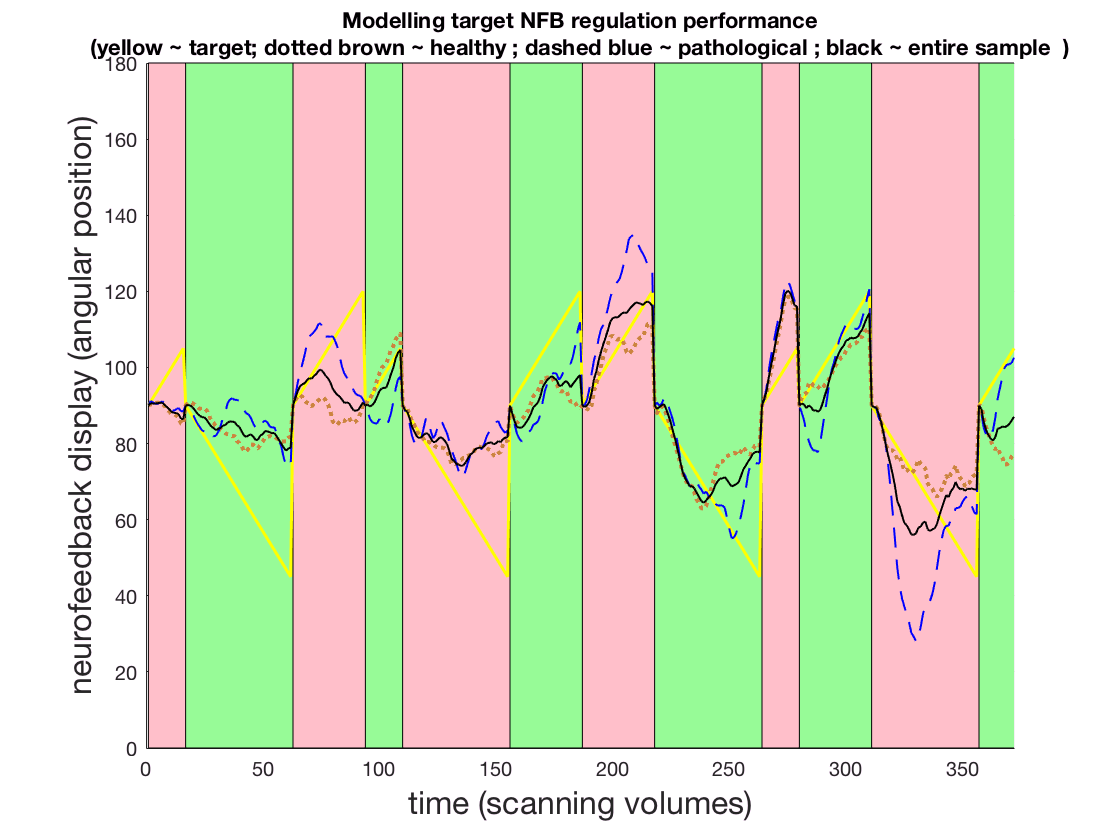

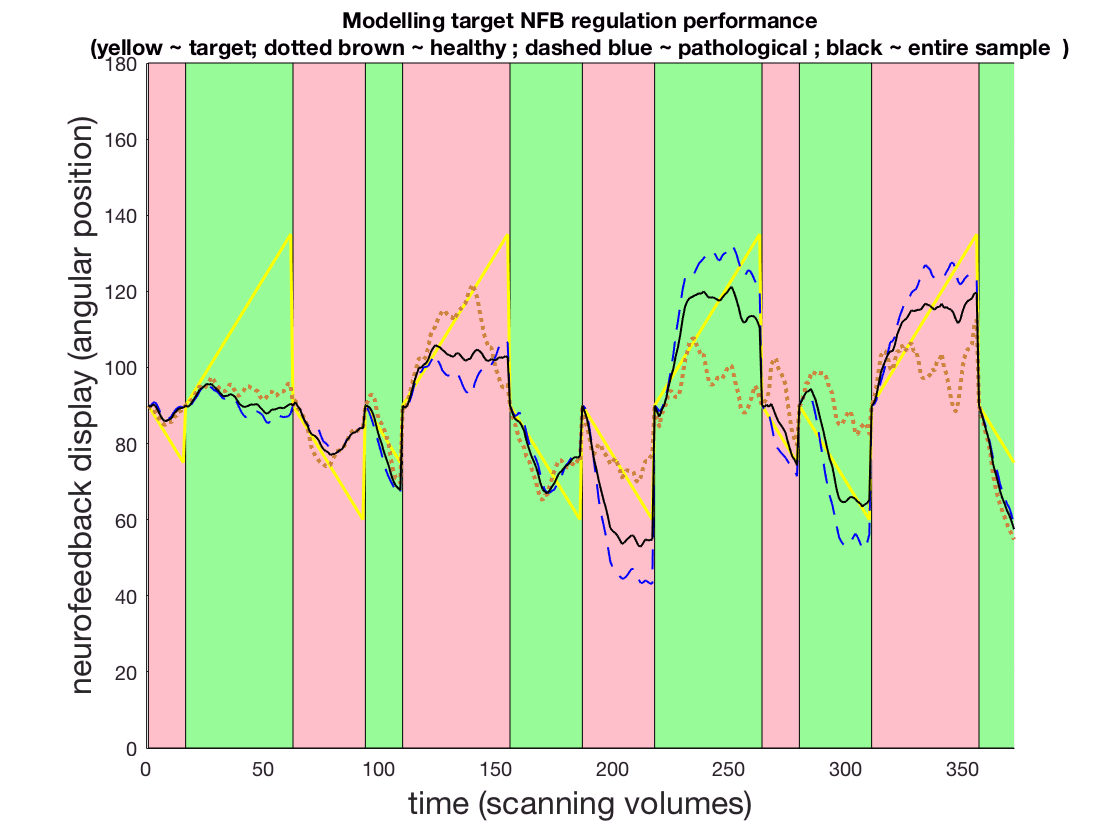

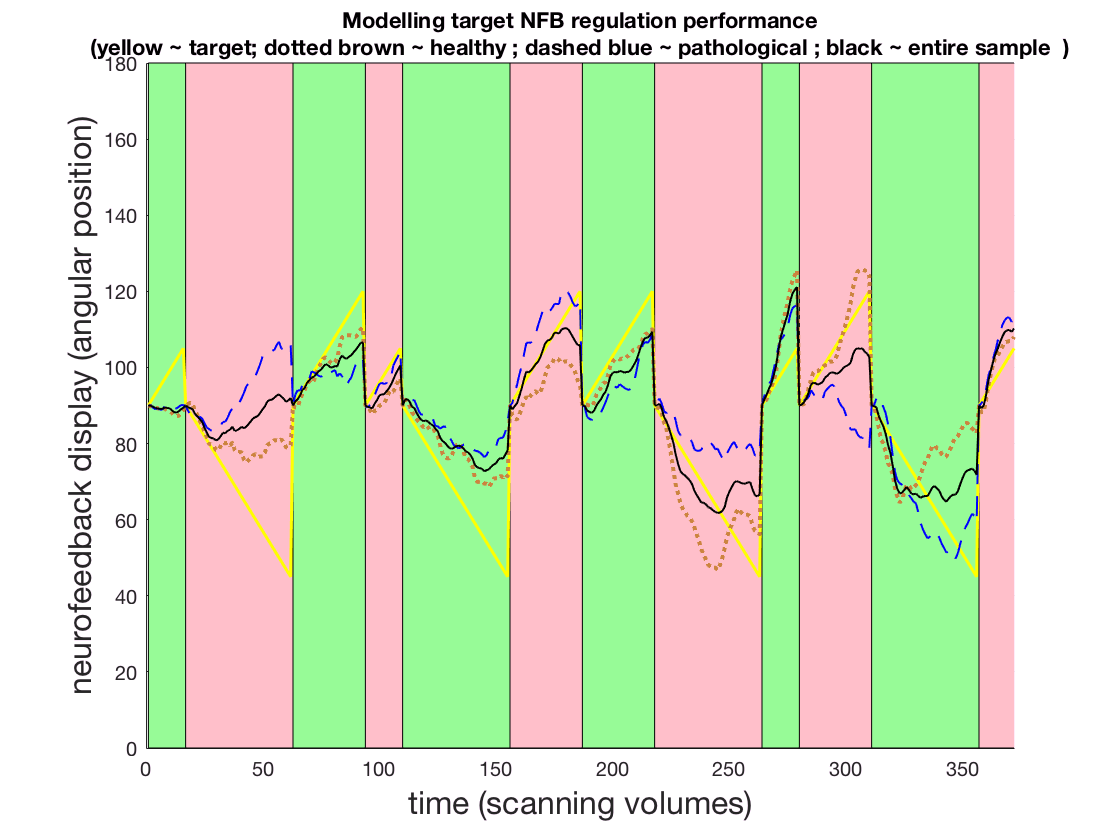

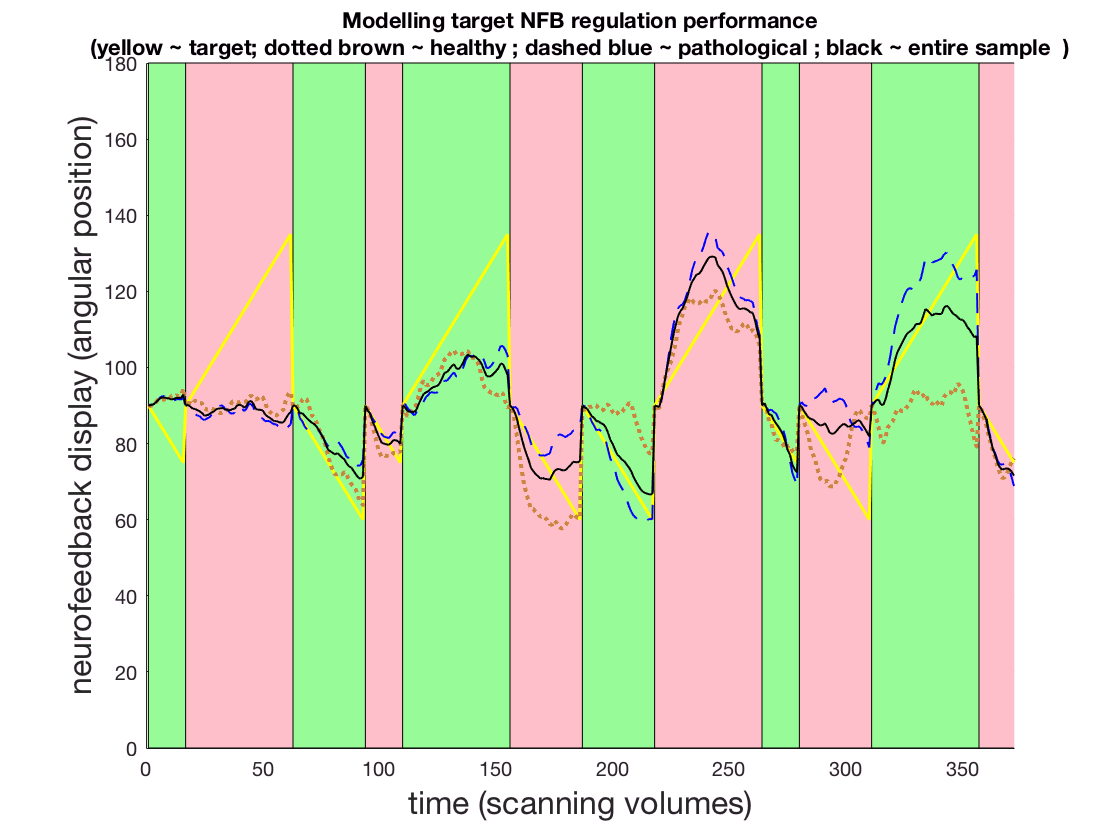

% Produce Fig. 1C (a graphical representation for visual inspection and validation of the approach for modelling neurofeedback regulation performance) 

covered=1; coveredTrialOrders{1}=[];
for s=1:length(SUB)
    
    % prepare subject's Trial Order string
    clear triOrd trialOrder; triOrd=char(SUB(s).trialOrder);
    subTrialOrder=[]; for e=1:24; subTrialOrder=[subTrialOrder '            ' triOrd(e,:)]; end
        
    % check if subject's trial order matches any of the covered trial orders
    match=0; coveredTrialOrders{covered}=[];
    for cvrd=1:covered
        if ~isempty(coveredTrialOrders{cvrd});
            
            % prepare current Trial Order string
            clear triOrd trialOrder; triOrd=char(coveredTrialOrders{cvrd});
            curTrialOrder=[]; for e=1:24; curTrialOrder=[curTrialOrder '            ' triOrd(e,:)]; end
            
            % compare subject and current trial orders
            if strcmp(subTrialOrder,curTrialOrder); 
                match=1;
                break; 
            end
        end
    end
    
    if match==0
        ref_sub=s;
        coveredTrialOrders{covered}       = SUB(ref_sub).trialOrder;
        subs_withSameTrialOrders{covered} = [ref_sub];
        clear SxT_ClinicalStatus % Subject x Trial Clinical Status

        for sub = ref_sub+1:length(SUB)
            if sum(strcmp(cellstr(SUB(ref_sub).trialOrder), cellstr(SUB(sub).trialOrder)))==24
                subs_withSameTrialOrders{covered} = [subs_withSameTrialOrders{covered} sub];
                if ClinicalStatus(sub)==1; SxT_ClinicalStatus(sub)=1; elseif ClinicalStatus(sub)==0; SxT_ClinicalStatus(sub)=2; end
            end

        end
    
    figure; 
    
    % Colour background 
    % (colour-selection optimized for discriminability across protanope and deuteranope colourblindness,
    % according to http://jfly.iam.u-tokyo.ac.jp/color/index.html and 
    % https://nl.mathworks.com/matlabcentral/fileexchange/24497-rgb-triple-of-color-name--version-2 )
    p=1; % position
    for T=1:12
        if strcmp(char(SUB(ref_sub).trialOrder(2*T-1)),'Focus'); 
            L = SUB(ref_sub).trial(T).length;
            patch([p p+L+1 p+L+1 p], [0 0 180*[1 1]], [1.0000    0.7500    0.7930]); % Pink
            p = p + L+1;       
        elseif strcmp(char(SUB(ref_sub).trialOrder(2*T-1)),'Wander'); 
            L = SUB(ref_sub).trial(T).length;
            patch([p p+L+1 p+L+1 p], [0 0 180*[1 1]], [0.5938    0.9833    0.5938]); % PaleGreen
            p = p + L+1;       
        else display(SUB(ref_sub).trialOrder(2*T-1))
             display(T)
             display(ref_sub)
        end
    end
        
    % Plot data
    hold on;
    xlabel('time (scanning volumes)', 'FontSize', 16);
    ylabel('neurofeedback display (angular position)', 'FontSize', 16);
    xlim([0 length(mean(NP_data( SxT_ClinicalStatus>=1,:)))])
    ylim([0 180 ])
    plot(SUB( subs_withSameTrialOrders{covered}(1) ).NP_linear, 'Color', [1 1 0], 'LineWidth', 1.5); % Yellow
    plot(mean(NP_data( SxT_ClinicalStatus==1,:) ), 'Color', [0.8008    0.5195    0.2461], 'LineStyle',':', 'LineWidth', 2); %LightBrown~"Peru" 
    plot(mean(NP_data( SxT_ClinicalStatus==2,:) ), 'Color', [0 0 1], 'LineStyle', '--', 'LineWidth', 1); %Blue
    plot(mean(NP_data( SxT_ClinicalStatus>=1,:)), 'k', 'LineWidth', 1); % Black
    title({'Modelling target NFB regulation performance', '(yellow ~ target; dotted brown ~ healthy ; dashed blue ~ pathological ; black ~ entire sample  )'});
    hold off;
    grid
    covered=covered+1;
    
    end
    
end

%%% INTERIM OBSERVATION: It is apparent that on average, NF regulation learning occured for both up- and down-regulation in all four trial orders and that performance improved considerably in the second half.

## section: Definition of variables for statistics

ClinicalStatus=ClinicalStatus;

age = age;

DMN_NF = mean(nanmean(NPEP_grand_linear(:,:,:),2),3);

DMN_NF_1stHalf = mean(nanmean(NPEP_grand_linear(:,1:6,:),2),3);

DMN_NF_2ndHalf = mean(nanmean(NPEP_grand_linear(:,7:12,:),2),3);

DMN_NF_UP=nanmean(NPEP_grand_linear(:,1:12,1),2);

DMN_NF_UP_1stHalf=nanmean(NPEP_grand_linear(:,1:6,1),2);

DMN_NF_UP_2ndHalf=nanmean(NPEP_grand_linear(:,7:12,1),2);

DMN_NF_DN=nanmean(NPEP_grand_linear(:,1:12,2),2);

DMN_NF_DN_1stHalf=nanmean(NPEP_grand_linear(:,1:6,2),2);

DMN_NF_DN_2ndHalf=nanmean(NPEP_grand_linear(:,7:12,2),2);

DMN_NF_learning = mean(nanmean(NPEP_grand_linear(:,7:12,:),2),3) - mean(nanmean(NPEP_grand_linear(:,1:6,:),2),3);

DMN_NF_UP_learning = nanmean(NPEP_grand_linear(:,7:12,1),2) - nanmean(NPEP_grand_linear(:,1:6,1),2);

DMN_NF_DN_learning = nanmean(NPEP_grand_linear(:,7:12,2),2) - nanmean(NPEP_grand_linear(:,1:6,2),2);


## section: Data cleaning

% Identify outliers in NF-regulation performance and learning (up-regulation, down-regulation or overall regulation).
% Outliers are identified according to the Grubbs test, recursively across all variables, until there are no more outliers left in any variable.

 while ~isempty(find(isoutlier(age(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_UP(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_DN(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_2ndHalf(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_UP_2ndHalf(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_DN_2ndHalf(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_learning(ClinicalStatus~=999),'grubbs')==1)) || ... 
    ~isempty(find(isoutlier(DMN_NF_UP_learning(ClinicalStatus~=999),'grubbs')==1)) || ...
    ~isempty(find(isoutlier(DMN_NF_DN_learning(ClinicalStatus~=999),'grubbs')==1));
 
    while ~isempty(find(isoutlier(age(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(age(ClinicalStatus~=999),'grubbs')==1)
        reduced=age(ClinicalStatus~=999); value=reduced(i)
        for v = 1:length(value)
            real_index=find(age==value(v)); display(real_index)    
            ClinicalStatus(find(age==value(v)))=999;
        end
    end

    while ~isempty(find(isoutlier(DMN_NF(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF(ClinicalStatus~=999); value=reduced(i)
        for v = 1:length(value)
            real_index=find(DMN_NF==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF==value(v)))=999;
        end
    end

    while ~isempty(find(isoutlier(DMN_NF_UP(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_UP(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_UP(ClinicalStatus~=999); value=reduced(i); 
        for v = 1:length(value)
            real_index=find(DMN_NF_UP==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_UP==value(v)))=999;
        end
    end
    
    while ~isempty(find(isoutlier(DMN_NF_DN(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_DN(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_DN(ClinicalStatus~=999); value=reduced(i);
        for v = 1:length(value)
            real_index=find(DMN_NF_DN==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_DN==value(v)))=999;
        end
    end

    while ~isempty(find(isoutlier(DMN_NF_2ndHalf(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_2ndHalf(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_2ndHalf(ClinicalStatus~=999); value=reduced(i)
        for v = 1:length(value)
            real_index=find(DMN_NF_2ndHalf==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_2ndHalf==value(v)))=999;
        end
    end

    while ~isempty(find(isoutlier(DMN_NF_UP_2ndHalf(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_UP_2ndHalf(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_UP_2ndHalf(ClinicalStatus~=999); value=reduced(i); 
        for v = 1:length(value)
            real_index=find(DMN_NF_UP_2ndHalf==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_UP_2ndHalf==value(v)))=999;
        end
    end
    
    while ~isempty(find(isoutlier(DMN_NF_DN_2ndHalf(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_DN_2ndHalf(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_DN_2ndHalf(ClinicalStatus~=999); value=reduced(i);
        for v = 1:length(value)
            real_index=find(DMN_NF_DN_2ndHalf==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_DN_2ndHalf==value(v)))=999;
        end
    end
    
    while ~isempty(find(isoutlier(DMN_NF_learning(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_learning(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_learning(ClinicalStatus~=999); value=reduced(i)
        for v = 1:length(value)
            real_index=find(DMN_NF_learning==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_learning==value(v)))=999;
        end
    end
    
    while ~isempty(find(isoutlier(DMN_NF_UP_learning(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_UP_learning(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_UP_learning(ClinicalStatus~=999); value=reduced(i)
        for v = 1:length(value)
            real_index=find(DMN_NF_UP_learning==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_UP_learning==value(v)))=999;
        end
    end
    
    while ~isempty(find(isoutlier(DMN_NF_DN_learning(ClinicalStatus~=999),'grubbs')==1)); 
        i=find(isoutlier(DMN_NF_DN_learning(ClinicalStatus~=999),'grubbs')==1)
        reduced=DMN_NF_DN_learning(ClinicalStatus~=999); value=reduced(i)
        for v = 1:length(value)
            real_index=find(DMN_NF_DN_learning==value(v)); display(real_index)    
            ClinicalStatus(find(DMN_NF_DN_learning==value(v)))=999;
        end
    end
end
outliers=find(ClinicalStatus==999)


outliers =

  0×1 empty double column vector



% No outliers have been identified.
 
% Clean variables from outliers (redundant in this case, however maintained for robustness in case of modifications)
 DMN_NF(ClinicalStatus==999)=[];             DMN_NF_1stHalf(ClinicalStatus==999)=[];        DMN_NF_2ndHalf(ClinicalStatus==999)=[]; 
 DMN_NF_UP(ClinicalStatus==999)=[];          DMN_NF_UP_1stHalf(ClinicalStatus==999)=[];     DMN_NF_UP_2ndHalf(ClinicalStatus==999)=[]; 
 DMN_NF_DN(ClinicalStatus==999)=[];          DMN_NF_DN_1stHalf(ClinicalStatus==999)=[];     DMN_NF_DN_2ndHalf(ClinicalStatus==999)=[]; 
 DMN_NF_learning(ClinicalStatus==999)=[];    DMN_NF_UP_learning(ClinicalStatus==999)=[];    DMN_NF_DN_learning(ClinicalStatus==999)=[];
 age(ClinicalStatus==999)=[]; ClinicalStatus(ClinicalStatus==999)=[]; 
 
 whos ClinicalStatus  age sex dexterity DMN_NF DMN_NF_1stHalf DMN_NF_2ndHalf DMN_NF_UP DMN_NF_UP_1stHalf DMN_NF_UP_2ndHalf ...
     DMN_NF_DN DMN_NF_DN_1stHalf DMN_NF_DN_2ndHalf DMN_NF_learning DMN_NF_UP_learning DMN_NF_DN_learning

  Name                      Size             Bytes  Class     Attributes

  ClinicalStatus          136x1               1088  double              
  DMN_NF                  136x1               1088  double              
  DMN_NF_1stHalf          136x1               1088  double              
  DMN_NF_2ndHalf          136x1               1088  double              
  DMN_NF_DN               136x1               1088  double              
  DMN_NF_DN_1stHalf       136x1               1088  double              
  DMN_NF_DN_2ndHalf       136x1               1088  double              
  DMN_NF_DN_learning      136x1               1088  double              
  DMN_NF_UP               136x1               1088  double              
  DMN_NF_UP_1stHalf       136x1               1088  double              
  DMN_NF_UP_2ndHalf       136x1               1088  double              
  DMN_NF_UP_learning      136x1               1088  double              
  DMN_NF_learning         136x1               1088

 % Save data of interest
 save DMN_NF.mat ClinicalStatus age sex dexterity DMN_NF DMN_NF_1stHalf DMN_NF_2ndHalf DMN_NF_UP DMN_NF_UP_1stHalf DMN_NF_UP_2ndHalf DMN_NF_DN DMN_NF_DN_1stHalf ...
     DMN_NF_DN_2ndHalf DMN_NF_learning DMN_NF_UP_learning DMN_NF_DN_learning
 
 % clear RAM from unnecessary variables
 clear; load DMN_NF.mat 
 
 % Export data to text file
 fid=fopen('DMN_NF_raw.txt', 'w')

fid = 3

 fprintf(fid, '%s \r', ['ClinicalStatus age DMN_NF_UP DMN_NF_UP_1stHalf DMN_NF_UP_2ndHalf DMN_NF_DN DMN_NF_DN_1stHalf DMN_NF_DN_2ndHalf DMN_NF_learning DMN_NF_UP_learning DMN_NF_DN_learning']);
 
 for s=1:length(ClinicalStatus)
     fprintf(fid, '%s \r', [num2str(ClinicalStatus(s)) ' ' num2str(age(s)) ' ' num2str(DMN_NF_UP(s)) ' ' num2str(DMN_NF_UP_1stHalf(s)) ' ' num2str(DMN_NF_UP_2ndHalf(s)) ' ' num2str(DMN_NF_DN(s)) ' ' ...
         num2str(DMN_NF_DN_1stHalf(s)) ' ' num2str(DMN_NF_DN_2ndHalf(s)) ' ' num2str(DMN_NF_learning(s)) ' ' num2str(DMN_NF_UP_learning(s)) ' ' num2str(DMN_NF_DN_learning(s))]);
 end
 fclose('all')

ans = 0

## section: Descriptive Statistics summarized in Figure 3 of the manuscript.

% All statistical estimates were computed explicitly, to facilitate quality control and reproducibility,
% as well as for demonstrative/educational purposes and for extending the analysis.

% 1st half session                                                                     % 2nd half session	
%     DMN UP-REGULATION	                                                               %     DMN UP-REGULATION	
%        Entire sample	                                                               %        Entire sample	
sample_mean_DMN_NF_UP_1stHalf       = mean(DMN_NF_UP_1stHalf(ClinicalStatus~=999));    sample_mean_DMN_NF_UP_2ndHalf       = mean(DMN_NF_UP_2ndHalf(ClinicalStatus~=999)); 
sample_sd_DMN_NF_UP_1stHalf         =  std(DMN_NF_UP_1stHalf(ClinicalStatus~=999));    sample_sd_DMN_NF_UP_2ndHalf         =  std(DMN_NF_UP_2ndHalf(ClinicalStatus~=999)); 
%        Control				                                       %        Control				
control_mean_DMN_NF_UP_1stHalf      = mean(DMN_NF_UP_1stHalf(ClinicalStatus==1));      control_mean_DMN_NF_UP_2ndHalf      = mean(DMN_NF_UP_2ndHalf(ClinicalStatus==1)); 
control_sd_DMN_NF_UP_1stHalf        =  std(DMN_NF_UP_1stHalf(ClinicalStatus==1));      control_sd_DMN_NF_UP_2ndHalf        =  std(DMN_NF_UP_2ndHalf(ClinicalStatus==1)); 
%        Pathological			                                               %        Pathological			
pathological_mean_DMN_NF_UP_1stHalf = mean(DMN_NF_UP_1stHalf(ClinicalStatus==0));      pathological_mean_DMN_NF_UP_2ndHalf = mean(DMN_NF_UP_2ndHalf(ClinicalStatus==0)); 
pathological_sd_DMN_NF_UP_1stHalf   =  std(DMN_NF_UP_1stHalf(ClinicalStatus==0));      pathological_sd_DMN_NF_UP_2ndHalf   =  std(DMN_NF_UP_2ndHalf(ClinicalStatus==0)); 
%     DMN DOWN-REGULATION	                                                       %     DMN DOWN-REGULATION	
%        Entire sample	                                                               %        Entire sample	
sample_mean_DMN_NF_DN_1stHalf       = mean(DMN_NF_DN_1stHalf(ClinicalStatus~=999));    sample_mean_DMN_NF_DN_2ndHalf       = mean(DMN_NF_DN_2ndHalf(ClinicalStatus~=999)); 
sample_sd_DMN_NF_DN_1stHalf         =  std(DMN_NF_DN_1stHalf(ClinicalStatus~=999));    sample_sd_DMN_NF_DN_2ndHalf         =  std(DMN_NF_DN_2ndHalf(ClinicalStatus~=999)); 
%        Control				                                       %        Control				
control_mean_DMN_NF_DN_1stHalf      = mean(DMN_NF_DN_1stHalf(ClinicalStatus==1));      control_mean_DMN_NF_DN_2ndHalf      = mean(DMN_NF_DN_2ndHalf(ClinicalStatus==1)); 
control_sd_DMN_NF_DN_1stHalf        =  std(DMN_NF_DN_1stHalf(ClinicalStatus==1));      control_sd_DMN_NF_DN_2ndHalf        =  std(DMN_NF_DN_2ndHalf(ClinicalStatus==1)); 
%        Pathological			                                               %        Pathological			
pathological_mean_DMN_NF_DN_1stHalf = mean(DMN_NF_DN_1stHalf(ClinicalStatus==0));      pathological_mean_DMN_NF_DN_2ndHalf = mean(DMN_NF_DN_2ndHalf(ClinicalStatus==0)); 
pathological_sd_DMN_NF_DN_1stHalf   =  std(DMN_NF_DN_1stHalf(ClinicalStatus==0));      pathological_sd_DMN_NF_DN_2ndHalf   =  std(DMN_NF_DN_2ndHalf(ClinicalStatus==0)); 
%     DMN OVERALL REGULATION                                                           %     DMN OVERALL REGULATION
%        Entire sample	                                                               %        Entire sample	
sample_mean_DMN_NF_1stHalf       = mean(DMN_NF_1stHalf(ClinicalStatus~=999));          sample_mean_DMN_NF_2ndHalf       = mean(DMN_NF_2ndHalf(ClinicalStatus~=999)); 
sample_sd_DMN_NF_1stHalf         =  std(DMN_NF_1stHalf(ClinicalStatus~=999));          sample_sd_DMN_NF_2ndHalf         =  std(DMN_NF_2ndHalf(ClinicalStatus~=999)); 
%        Control				                                       %        Control				
control_mean_DMN_NF_1stHalf      = mean(DMN_NF_1stHalf(ClinicalStatus==1));            control_mean_DMN_NF_2ndHalf      = mean(DMN_NF_2ndHalf(ClinicalStatus==1)); 
control_sd_DMN_NF_1stHalf        =  std(DMN_NF_1stHalf(ClinicalStatus==1));            control_sd_DMN_NF_2ndHalf        =  std(DMN_NF_2ndHalf(ClinicalStatus==1)); 
%        Pathological			                                               %        Pathological			
pathological_mean_DMN_NF_1stHalf = mean(DMN_NF_1stHalf(ClinicalStatus==0));            pathological_mean_DMN_NF_2ndHalf = mean(DMN_NF_2ndHalf(ClinicalStatus==0)); 
pathological_sd_DMN_NF_1stHalf   =  std(DMN_NF_1stHalf(ClinicalStatus==0));            pathological_sd_DMN_NF_2ndHalf   =  std(DMN_NF_2ndHalf(ClinicalStatus==0)); 

%Entire session	                                                                       % Learning score
%     DMN UP-REGULATION	                                                               %     DMN UP-REGULATION	
%        Entire sample	                                                               %        Entire sample	
sample_mean_DMN_NF_UP       = mean(DMN_NF_UP(ClinicalStatus~=999));                    sample_mean_DMN_NF_UP_learning       = mean(DMN_NF_UP_2ndHalf(ClinicalStatus~=999) - DMN_NF_UP_1stHalf(ClinicalStatus~=999)); 
sample_sd_DMN_NF_UP         =  std(DMN_NF_UP(ClinicalStatus~=999));                    sample_sd_DMN_NF_UP_learning         =  std(DMN_NF_UP_2ndHalf(ClinicalStatus~=999) - DMN_NF_UP_1stHalf(ClinicalStatus~=999)); 
%        Control				                                       %        Control				
control_mean_DMN_NF_UP      = mean(DMN_NF_UP(ClinicalStatus==1));                      control_mean_DMN_NF_UP_learning      = mean(DMN_NF_UP_2ndHalf(ClinicalStatus==1)  - DMN_NF_UP_1stHalf(ClinicalStatus==1)); 
control_sd_DMN_NF_UP        =  std(DMN_NF_UP(ClinicalStatus==1));                      control_sd_DMN_NF_UP_learning        =  std(DMN_NF_UP_2ndHalf(ClinicalStatus==1)  - DMN_NF_UP_1stHalf(ClinicalStatus==1)); 
%        Pathological			                                               %        Pathological			
pathological_mean_DMN_NF_UP = mean(DMN_NF_UP(ClinicalStatus==0));                      pathological_mean_DMN_NF_UP_learning = mean(DMN_NF_UP_2ndHalf(ClinicalStatus==0)  - DMN_NF_UP_1stHalf(ClinicalStatus==0));
pathological_sd_DMN_NF_UP   =  std(DMN_NF_UP(ClinicalStatus==0));                      pathological_sd_DMN_NF_UP_learning   =  std(DMN_NF_UP_2ndHalf(ClinicalStatus==0)  - DMN_NF_UP_1stHalf(ClinicalStatus==0));
%     DMN DOWN-REGULATION	                                                       %     DMN DOWN-REGULATION	
%        Entire sample	                                                               %        Entire sample	
sample_mean_DMN_NF_DN       = mean(DMN_NF_DN(ClinicalStatus~=999));                    sample_mean_DMN_NF_DN_learning       = mean(DMN_NF_DN_2ndHalf(ClinicalStatus~=999) - DMN_NF_DN_1stHalf(ClinicalStatus~=999));
sample_sd_DMN_NF_DN         =  std(DMN_NF_DN(ClinicalStatus~=999));                    sample_sd_DMN_NF_DN_learning         =  std(DMN_NF_DN_2ndHalf(ClinicalStatus~=999) - DMN_NF_DN_1stHalf(ClinicalStatus~=999));
%        Control				                                       %        Control				
control_mean_DMN_NF_DN      = mean(DMN_NF_DN(ClinicalStatus==1));                      control_mean_DMN_NF_DN_learning      = mean(DMN_NF_DN_2ndHalf(ClinicalStatus==1) - DMN_NF_DN_1stHalf(ClinicalStatus==1)); 
control_sd_DMN_NF_DN        =  std(DMN_NF_DN(ClinicalStatus==1));                      control_sd_DMN_NF_DN_learning        =  std(DMN_NF_DN_2ndHalf(ClinicalStatus==1) - DMN_NF_DN_1stHalf(ClinicalStatus==1)); 
%        Pathological			                                               %        Pathological			
pathological_mean_DMN_NF_DN = mean(DMN_NF_DN(ClinicalStatus==0));                      pathological_mean_DMN_NF_DN_learning = mean(DMN_NF_DN_2ndHalf(ClinicalStatus==0) - DMN_NF_DN_1stHalf(ClinicalStatus==0)); 
pathological_sd_DMN_NF_DN   =  std(DMN_NF_DN(ClinicalStatus==0));                      pathological_sd_DMN_NF_DN_learning   =  std(DMN_NF_DN_2ndHalf(ClinicalStatus==0) - DMN_NF_DN_1stHalf(ClinicalStatus==0)); 
%     DMN OVERALL REGULATION                                                           %     DMN OVERALL REGULATION
%        Entire sample	                                                               %        Entire sample	
sample_mean_DMN_NF       = mean(DMN_NF(ClinicalStatus~=999));                          sample_mean_DMN_NF_learning       = mean(DMN_NF_2ndHalf(ClinicalStatus~=999) - DMN_NF_1stHalf(ClinicalStatus~=999));
sample_sd_DMN_NF         =  std(DMN_NF(ClinicalStatus~=999));                          sample_sd_DMN_NF_learning         =  std(DMN_NF_2ndHalf(ClinicalStatus~=999) - DMN_NF_1stHalf(ClinicalStatus~=999));
%        Control				                                       %        Control				
control_mean_DMN_NF      = mean(DMN_NF(ClinicalStatus==1));                            control_mean_DMN_NF_learning      = mean(DMN_NF_2ndHalf(ClinicalStatus==1) - DMN_NF_1stHalf(ClinicalStatus==1)); 
control_sd_DMN_NF        =  std(DMN_NF(ClinicalStatus==1));                            control_sd_DMN_NF_learning        =  std(DMN_NF_2ndHalf(ClinicalStatus==1) - DMN_NF_1stHalf(ClinicalStatus==1)); 
%        Pathological			                                               %        Pathological			
pathological_mean_DMN_NF = mean(DMN_NF(ClinicalStatus==0));                            pathological_mean_DMN_NF_learning = mean(DMN_NF_2ndHalf(ClinicalStatus==0) - DMN_NF_1stHalf(ClinicalStatus==0)); 
pathological_sd_DMN_NF   =  std(DMN_NF(ClinicalStatus==0));                            pathological_sd_DMN_NF_learning   =  std(DMN_NF_2ndHalf(ClinicalStatus==0) - DMN_NF_1stHalf(ClinicalStatus==0)); 

% save statistical estimates
save Table_1.mat ...
sample_mean_DMN_NF_UP  sample_sd_DMN_NF_UP sample_mean_DMN_NF_UP_1stHalf  sample_sd_DMN_NF_UP_1stHalf	sample_mean_DMN_NF_UP_2ndHalf sample_sd_DMN_NF_UP_2ndHalf	sample_mean_DMN_NF_UP_learning  sample_sd_DMN_NF_UP_learning ...
control_mean_DMN_NF_UP control_sd_DMN_NF_UP	control_mean_DMN_NF_UP_1stHalf control_sd_DMN_NF_UP_1stHalf	control_mean_DMN_NF_UP_2ndHalf control_sd_DMN_NF_UP_2ndHalf	control_mean_DMN_NF_UP_learning  control_sd_DMN_NF_UP_learning ...
pathological_mean_DMN_NF_UP  pathological_sd_DMN_NF_UP	pathological_mean_DMN_NF_UP_1stHalf  pathological_sd_DMN_NF_UP_1stHalf	pathological_mean_DMN_NF_UP_2ndHalf  pathological_sd_DMN_NF_UP_2ndHalf	pathological_mean_DMN_NF_UP_learning  pathological_sd_DMN_NF_UP_learning ...
sample_mean_DMN_NF_DN  sample_sd_DMN_NF_DN	sample_mean_DMN_NF_DN_1stHalf  sample_sd_DMN_NF_DN_1stHalf	sample_mean_DMN_NF_DN_2ndHalf  sample_sd_DMN_NF_DN_2ndHalf	sample_mean_DMN_NF_DN_learning  sample_sd_DMN_NF_DN_learning ...
control_mean_DMN_NF_DN  control_sd_DMN_NF_DN	control_mean_DMN_NF_DN_1stHalf  control_sd_DMN_NF_DN_1stHalf	control_mean_DMN_NF_DN_2ndHalf  control_sd_DMN_NF_DN_2ndHalf	control_mean_DMN_NF_DN_learning  control_sd_DMN_NF_DN_learning ...
pathological_mean_DMN_NF_DN  pathological_sd_DMN_NF_DN	pathological_mean_DMN_NF_DN_1stHalf  pathological_sd_DMN_NF_DN_1stHalf	pathological_mean_DMN_NF_DN_2ndHalf  pathological_sd_DMN_NF_DN_2ndHalf	pathological_mean_DMN_NF_DN_learning  pathological_sd_DMN_NF_DN_learning ...
sample_mean_DMN_NF  sample_sd_DMN_NF	sample_mean_DMN_NF_1stHalf  sample_sd_DMN_NF_1stHalf	sample_mean_DMN_NF_2ndHalf  sample_sd_DMN_NF_2ndHalf	sample_mean_DMN_NF_learning  sample_sd_DMN_NF_learning ...
control_mean_DMN_NF  control_sd_DMN_NF	control_mean_DMN_NF_1stHalf  control_sd_DMN_NF_1stHalf	control_mean_DMN_NF_2ndHalf  control_sd_DMN_NF_2ndHalf	control_mean_DMN_NF_learning  control_sd_DMN_NF_learning ...
pathological_mean_DMN_NF  pathological_sd_DMN_NF	pathological_mean_DMN_NF_1stHalf  pathological_sd_DMN_NF_1stHalf	pathological_mean_DMN_NF_2ndHalf  pathological_sd_DMN_NF_2ndHalf	pathological_mean_DMN_NF_learning  pathological_sd_DMN_NF_learning

% Compute demographics

mean(age)

ans = 30.7059

std(age)

ans = 7.2848

mean(age(ClinicalStatus==1))

ans = 30.7097

std(age(ClinicalStatus==1))

ans = 7.4798

mean(age(ClinicalStatus==0))

ans = 30.7027

std(age(ClinicalStatus==0))

ans = 7.1687

nnz(sex==1)                            % 77 females out of 136 participants

ans = 77

nnz(dexterity==1)                      % 122 righ-handed out of 136 participants

ans = 122

nnz(sex(ClinicalStatus==1)==1)         % 36 females out of 62 participants in control group

ans = 36

nnz(dexterity(ClinicalStatus==1)==1)   % 56 right-handed out of 62 participants in control group

ans = 56

nnz(sex(ClinicalStatus==0)==1)         % 41 females out of 74 participants in pathological group

ans = 41

nnz(dexterity(ClinicalStatus==0)==1)   % 66 right-handed out of 74 participants in pathological group

ans = 66

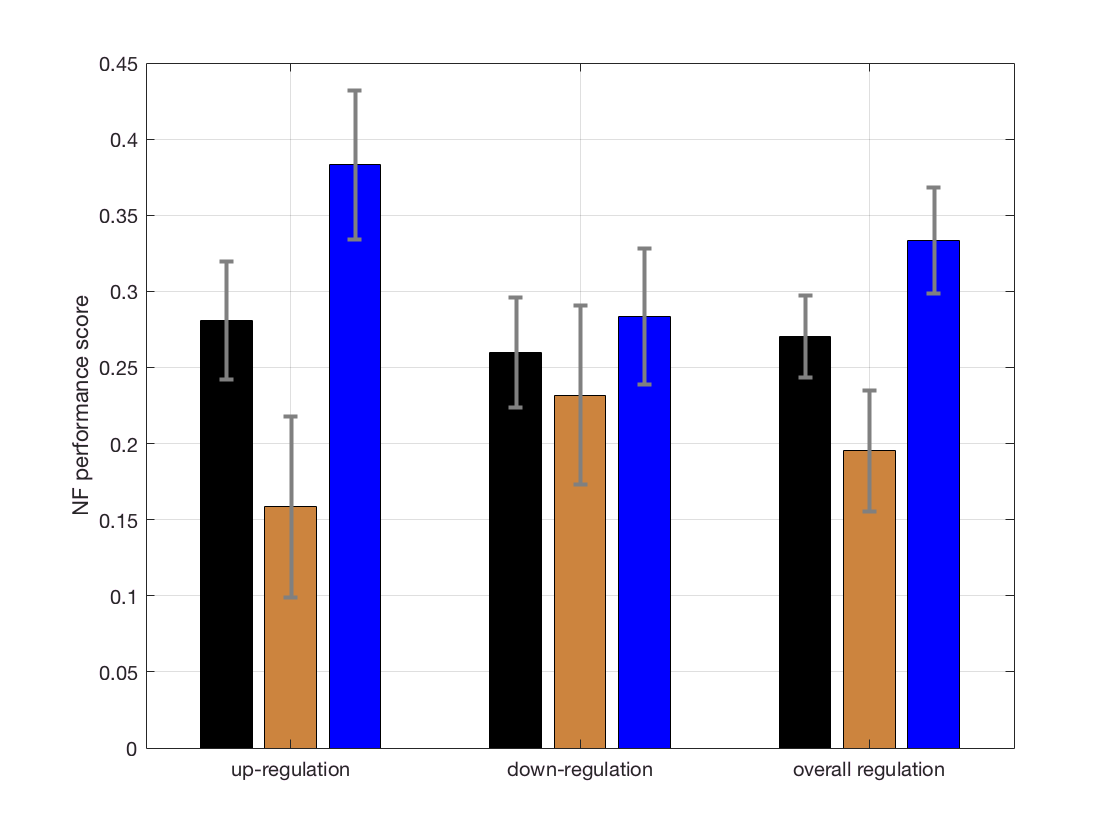

% Plot Bar Graphs with Error bars 
% using barwitherr.m (available from https://nl.mathworks.com/matlabcentral/fileexchange/30639-barwitherr-errors-varargin- )

% Neurofeedback performance score

figure; 
E=[ sample_sd_DMN_NF_UP_2ndHalf/sqrt(136)  control_sd_DMN_NF_UP_2ndHalf/sqrt(62)  pathological_sd_DMN_NF_UP_2ndHalf/sqrt(74) ; ...
    sample_sd_DMN_NF_DN_2ndHalf/sqrt(136)  control_sd_DMN_NF_DN_2ndHalf/sqrt(62)  pathological_sd_DMN_NF_DN_2ndHalf/sqrt(74) ; ...
    sample_sd_DMN_NF_2ndHalf/sqrt(136)     control_sd_DMN_NF_2ndHalf/sqrt(62)     pathological_sd_DMN_NF_2ndHalf/sqrt(74)]  ;

Y=[ sample_mean_DMN_NF_UP_2ndHalf  control_mean_DMN_NF_UP_2ndHalf  pathological_mean_DMN_NF_UP_2ndHalf ; ...
    sample_mean_DMN_NF_DN_2ndHalf  control_mean_DMN_NF_DN_2ndHalf  pathological_mean_DMN_NF_DN_2ndHalf ; ...
    sample_mean_DMN_NF_2ndHalf     control_mean_DMN_NF_2ndHalf     pathological_mean_DMN_NF_2ndHalf] ;

clr = [0 0 0;  0.8008    0.5195    0.2461;   0 0 1];
colormap(clr);

barwitherr(E,Y)
xticks([1 2 3])
xticklabels({'up-regulation','down-regulation','overall regulation'})
ylabel('NF performance score')
grid

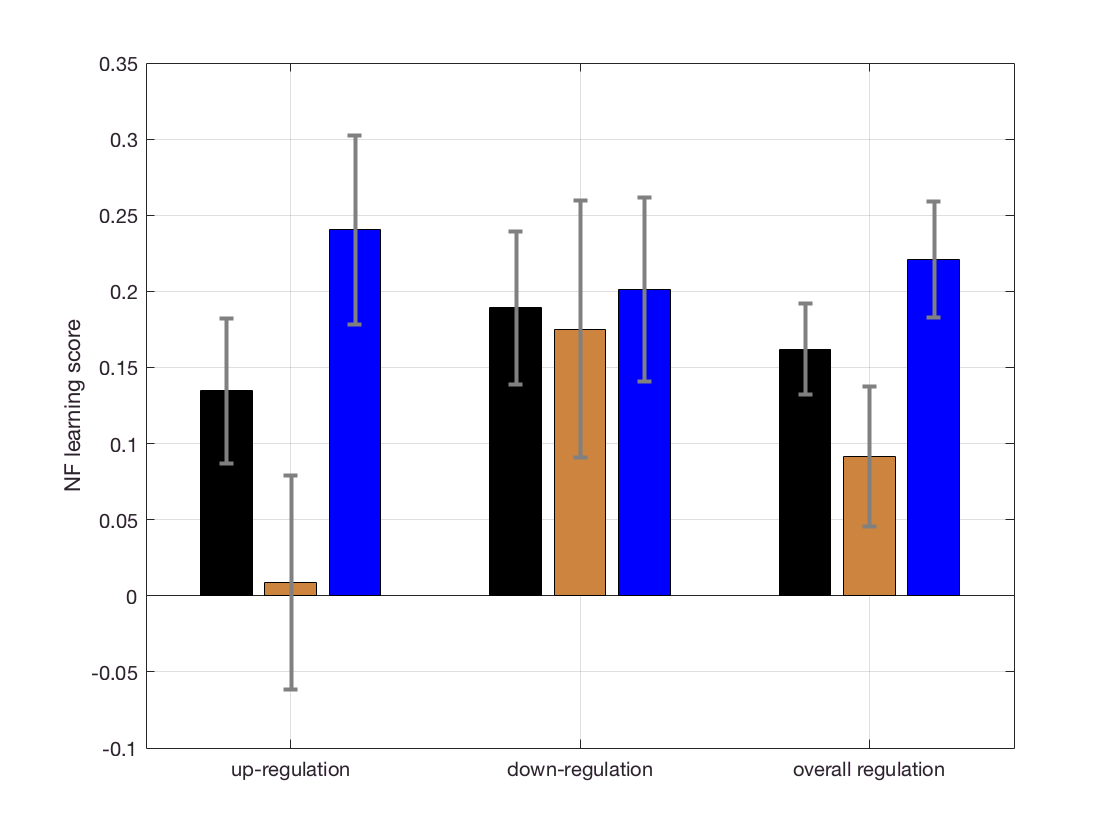


% Neurofeedback learning score

figure;
E=[ sample_sd_DMN_NF_UP_learning/sqrt(136)  control_sd_DMN_NF_UP_learning/sqrt(62)  pathological_sd_DMN_NF_UP_learning/sqrt(74) ; ...
    sample_sd_DMN_NF_DN_learning/sqrt(136)  control_sd_DMN_NF_DN_learning/sqrt(62)  pathological_sd_DMN_NF_DN_learning/sqrt(74) ; ...
    sample_sd_DMN_NF_learning/sqrt(136)     control_sd_DMN_NF_learning/sqrt(62)     pathological_sd_DMN_NF_learning/sqrt(74)]  ;

Y=[ sample_mean_DMN_NF_UP_learning  control_mean_DMN_NF_UP_learning  pathological_mean_DMN_NF_UP_learning ; ...
    sample_mean_DMN_NF_DN_learning  control_mean_DMN_NF_DN_learning  pathological_mean_DMN_NF_DN_learning ; ...
    sample_mean_DMN_NF_learning     control_mean_DMN_NF_learning     pathological_mean_DMN_NF_learning] ;

clr = [0 0 0;  0.8008    0.5195    0.2461;   0 0 1];
colormap(clr);

BwE=barwitherr(E,Y);

xticks([1 2 3])
xticklabels({'up-regulation','down-regulation','overall regulation'})
ylabel('NF learning score')
grid

## section: Hypothesis testing part 1

% Research question: Is there any evidence of DMN NF associations with age?

if lillietest(age)~=0; display('normality violation'); end

normality violation


% Age is not normally distributed. We therefore perform correlation testing using Spearman's rho

% Control group
[RHO,PVAL] = corr(DMN_NF_2ndHalf(ClinicalStatus==1),age(ClinicalStatus==1)','type','Spearman')

RHO = -0.4124

PVAL = 8.6559e-04

% Pathological group
[RHO,PVAL] = corr(DMN_NF_2ndHalf(ClinicalStatus==0),age(ClinicalStatus==0)','type','Spearman')

RHO = -0.0711

PVAL = 0.5473

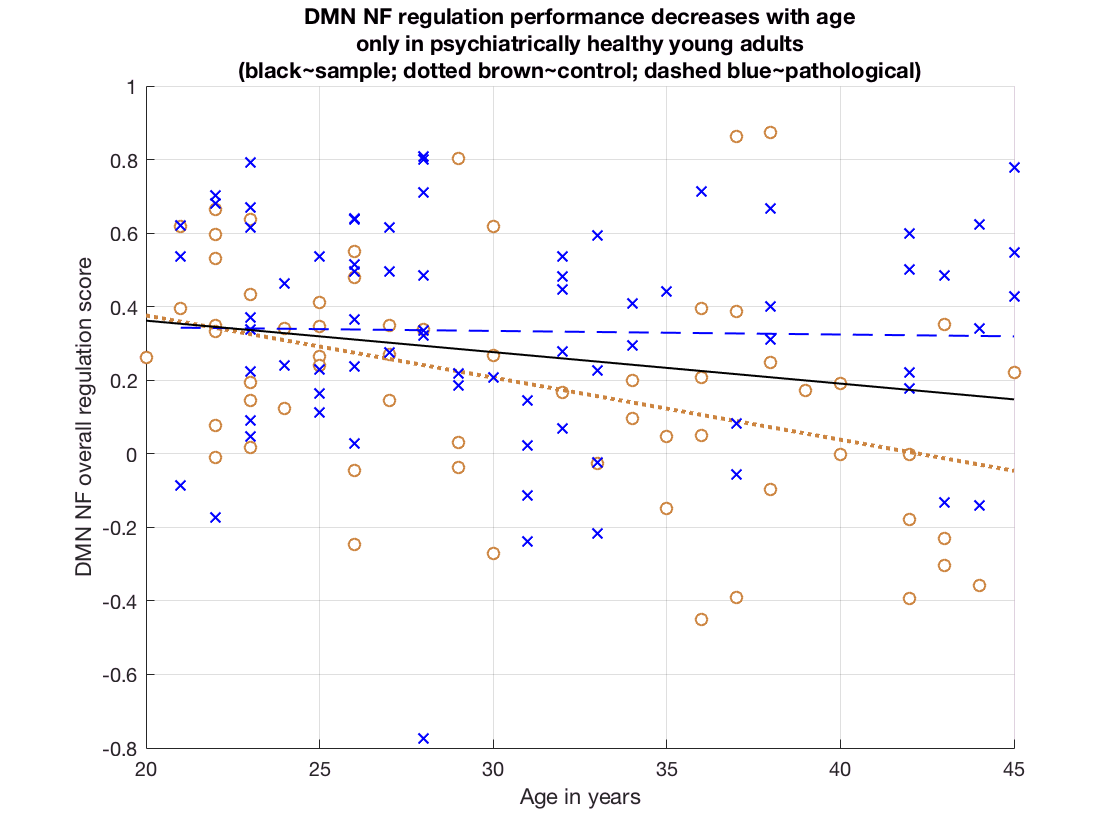


% Initial DMN NF regulation score correlates negatively with age, only in subjects with no psychiatric history (r=-0.412, p=0.0009, R2=0.17). 

% FIGURE 2: DMN NFB regulation performance dencreases with age in psychiatrically healthy young adults 
figure; hold on; 
scatter(age(ClinicalStatus==1)',DMN_NF_2ndHalf(ClinicalStatus==1),'o','MarkerFaceColor', [1 1 1],'MarkerEdgeColor', [0.8008    0.5195    0.2461])
x=age(ClinicalStatus==1)'; y=DMN_NF_2ndHalf(ClinicalStatus==1);
coeffs = polyfit(x, y, 1); fittedX = linspace(min(x), max(x), 200); fittedY = polyval(coeffs, fittedX); plot(fittedX, fittedY, 'm-', 'Color', [0.8008    0.5195    0.2461], 'LineStyle',':', 'LineWidth', 2); %LightBrown~"Peru" ); 
scatter(age(ClinicalStatus==0)',DMN_NF_2ndHalf(ClinicalStatus==0),'x','MarkerFaceColor', [0 0 1],'MarkerEdgeColor', [0 0 1])
x=age(ClinicalStatus==0)'; y=DMN_NF_2ndHalf(ClinicalStatus==0);
coeffs = polyfit(x, y, 1); fittedX = linspace(min(x), max(x), 200); fittedY = polyval(coeffs, fittedX); plot(fittedX, fittedY, 'm-', 'Color', [0 0 1], 'LineStyle', '--', 'LineWidth', 1); %Blue
x=age'; y=DMN_NF_2ndHalf(ClinicalStatus~=999); % all subjects
coeffs = polyfit(x, y, 1); fittedX = linspace(min(x), max(x), 200); fittedY = polyval(coeffs, fittedX); plot(fittedX, fittedY, 'm-', 'LineWidth', 1, 'Color','k'); 
xlabel('Age in years');
ylabel('DMN NF overall regulation score');
title({'DMN NF regulation performance decreases with age', 'only in psychiatrically healthy young adults', '(black~sample; dotted brown~control; dashed blue~pathological)'});hold off;
grid

## section: Hypothesis testing part 2

% Research question: Is initial NF learning bidirectional or direction-specific?

% clear RAM from unnecessary variables
clear; load DMN_NF.mat 

% check that variables do not deviate from normality
if lillietest(DMN_NF_UP_learning)~=0; display('normality violation'); end
if lillietest(DMN_NF_DN_learning)~=0; display('normality violation'); end

% Perform correlation test
[RHO,PVAL] = corr(DMN_NF_UP_learning,DMN_NF_DN_learning)

RHO = -0.2586

PVAL = 0.0024

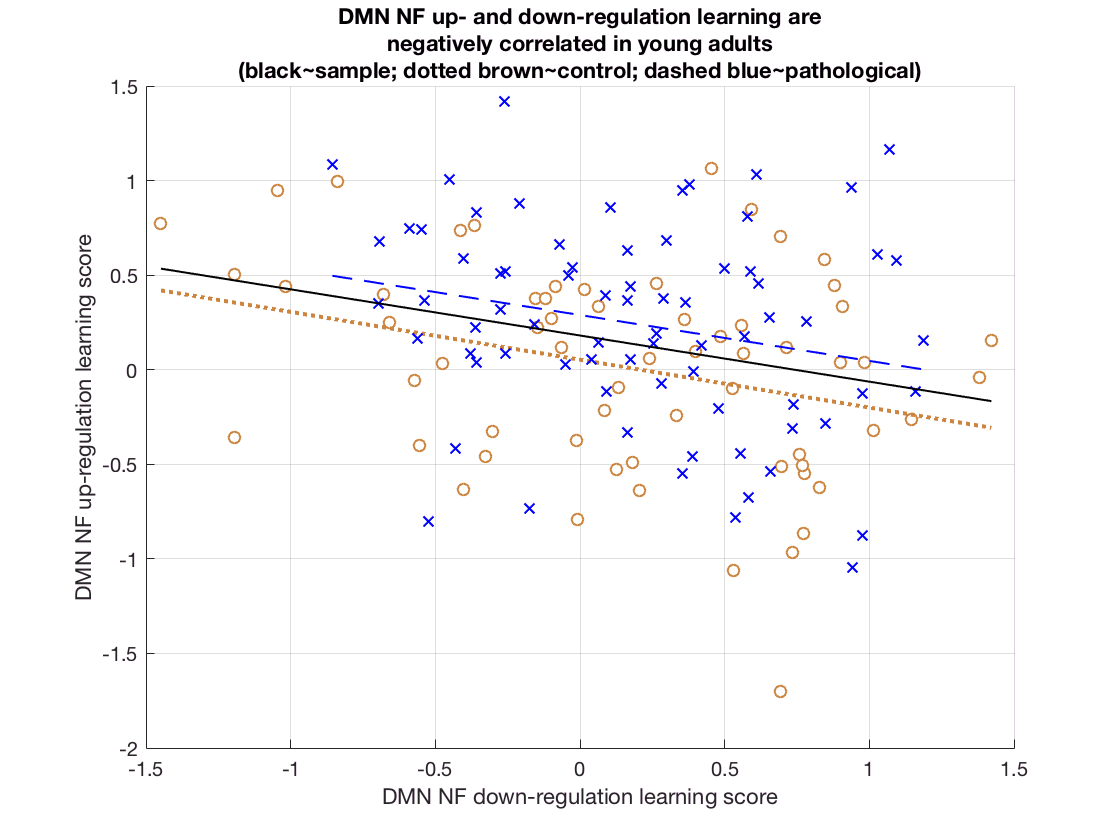

% Correlation testing suggests that in the present sample of young adults, the initial DMN NF up- and down-regulation learning scores are significantly negatively correlated,
% albeit with weak association  (r=-0.258, p=0.0024, R2=0.067).
    
% Scatter plot: DMN NFB up- and down- regulation learning  are negatively correlated in young adults
figure; hold on; 
scatter(DMN_NF_DN_learning(ClinicalStatus==1), DMN_NF_UP_learning(ClinicalStatus==1), 'o','MarkerFaceColor', [1 1 1],'MarkerEdgeColor', [0.8008    0.5195    0.2461])
y=DMN_NF_UP_learning(ClinicalStatus==1); % up-regulation on y
x=DMN_NF_DN_learning(ClinicalStatus==1); % down-regulation on x
coeffs = polyfit(x, y, 1); fittedX = linspace(min(x), max(x), 200); fittedY = polyval(coeffs, fittedX); plot(fittedX, fittedY, 'm-', 'Color', [0.8008    0.5195    0.2461], 'LineStyle',':', 'LineWidth', 2); %LightBrown~"Peru" ); 
scatter(DMN_NF_DN_learning(ClinicalStatus==0), DMN_NF_UP_learning(ClinicalStatus==0), 'x', 'MarkerFaceColor', [0 0 1],'MarkerEdgeColor', [0 0 1])
y=DMN_NF_UP_learning(ClinicalStatus==0); % up-regulation on y
x=DMN_NF_DN_learning(ClinicalStatus==0); % down-regulation on x
coeffs = polyfit(x, y, 1); fittedX = linspace(min(x), max(x), 200); fittedY = polyval(coeffs, fittedX); plot(fittedX, fittedY, 'm-', 'Color', [0 0 1], 'LineStyle', '--', 'LineWidth', 1); %Blue
y=DMN_NF_UP_learning; % up-regulation on y
x=DMN_NF_DN_learning; % down-regulation on x
coeffs = polyfit(x, y, 1); fittedX = linspace(min(x), max(x), 200); fittedY = polyval(coeffs, fittedX); plot(fittedX, fittedY, 'm-', 'LineWidth', 1, 'Color','k'); 
xlabel('DMN NF down-regulation learning score');
ylabel('DMN NF up-regulation learning score');
title({'DMN NF up- and down-regulation learning are', 'negatively correlated in young adults', '(black~sample; dotted brown~control; dashed blue~pathological)'}); hold off;
grid

## section: Hypothesis testing part 3

% Research question: Is there any evidence of difference in NF performance between controls and subjects with a psychiatric history (pathological group)?
% 
% Having found that up- and down-correlation are negatively correlated, we presume that the two processes do not necessarily share the same neural correlates 
% and we investigate up- and down-regulation independently.
% 
% Moreover, because of the evident learning effect (see Figures 1 & 3 in manuscript), we consider the 1st half as practise and compute NF-performance based on 2nd half of the session.

% Perform independent samples permutation t-tests

% Up-regulation
[P t]=mult_comp_perm_t2(DMN_NF_UP_2ndHalf(ClinicalStatus==1),DMN_NF_UP_2ndHalf(ClinicalStatus==0),100000)

Pooled variance (i.e., standard independent samples) t-statistic will be used.


mult_comp_perm_t2: Number of variables: 1
mult_comp_perm_t2: Number of observations in Data Set 1: 62
mult_comp_perm_t2: Number of observations in Data Set 2: 74
t-score degrees of freedom: 134
Executing permutation test with 100000 permutations...
Permutations completed: 100, 200, 300, 400, 500, 600, 700, 800, 900, 1000
1100, 1200, 1300, 1400, 1500, 1600, 1700, 1800, 1900, 2000
2100, 2200, 2300, 2400, 2500, 2600, 2700, 2800, 2900, 3000
3100, 3200, 3300, 3400, 3500, 3600, 3700, 3800, 3900, 4000
4100, 4200, 4300, 4400, 4500, 4600, 4700, 4800, 4900, 5000
5100, 5200, 5300, 5400, 5500, 5600, 5700, 5800, 5900, 6000
6100, 6200, 6300, 6400, 6500, 6600, 6700, 6800, 6900, 7000
7100, 7200, 7300, 7400, 7500, 7600, 7700, 7800, 7900, 8000
8100, 8200, 8300, 8400, 8500, 8600, 8700, 8800, 8900, 9000
9100, 9200, 9300, 9400, 9500, 9600, 9700, 9800, 9900, 10000
10100, 10200, 10300, 10400, 10500, 10600, 10700, 10800, 10900, 11000
11100, 11200, 11300, 11400, 11500, 11600, 11700, 11800, 11900, 12000
12100, 

P = 0.0036

t = -2.9509

% Down-regulation
[P t]=mult_comp_perm_t2(DMN_NF_DN_2ndHalf(ClinicalStatus==1),DMN_NF_DN_2ndHalf(ClinicalStatus==0),100000)

Pooled variance (i.e., standard independent samples) t-statistic will be used.


mult_comp_perm_t2: Number of variables: 1
mult_comp_perm_t2: Number of observations in Data Set 1: 62
mult_comp_perm_t2: Number of observations in Data Set 2: 74
t-score degrees of freedom: 134
Executing permutation test with 100000 permutations...
Permutations completed: 100, 200, 300, 400, 500, 600, 700, 800, 900, 1000
1100, 1200, 1300, 1400, 1500, 1600, 1700, 1800, 1900, 2000
2100, 2200, 2300, 2400, 2500, 2600, 2700, 2800, 2900, 3000
3100, 3200, 3300, 3400, 3500, 3600, 3700, 3800, 3900, 4000
4100, 4200, 4300, 4400, 4500, 4600, 4700, 4800, 4900, 5000
5100, 5200, 5300, 5400, 5500, 5600, 5700, 5800, 5900, 6000
6100, 6200, 6300, 6400, 6500, 6600, 6700, 6800, 6900, 7000
7100, 7200, 7300, 7400, 7500, 7600, 7700, 7800, 7900, 8000
8100, 8200, 8300, 8400, 8500, 8600, 8700, 8800, 8900, 9000
9100, 9200, 9300, 9400, 9500, 9600, 9700, 9800, 9900, 10000
10100, 10200, 10300, 10400, 10500, 10600, 10700, 10800, 10900, 11000
11100, 11200, 11300, 11400, 11500, 11600, 11700, 11800, 11900, 12000
12100, 

P = 0.4742

t = -0.7113

% Contrary to our expectations, independent samples t-tests show that young adults with a psychiatric history perform significantly better in initial DMN NF 
% up-regulation (wandering) than controls (t(134)=-2.951, p=0.0036) and not significantly better in DMN down-regulation performance (focus), although still better.  